# 音调与节拍分析

｜ 初始操作：

clear all; close all; clc;
[y, fs] = audioread('fmt.wav');
len = length(y);
index = 1:len;

## 1.音符分割的实现

### 主要思想

- 形成包络波形：首先使用findpeaks函数定位极大值，光滑处理得到包络波形。

- 寻找包络峰值：再对包络波形求解极大值作做作为音符分割点。

### 核心代码

包络形成

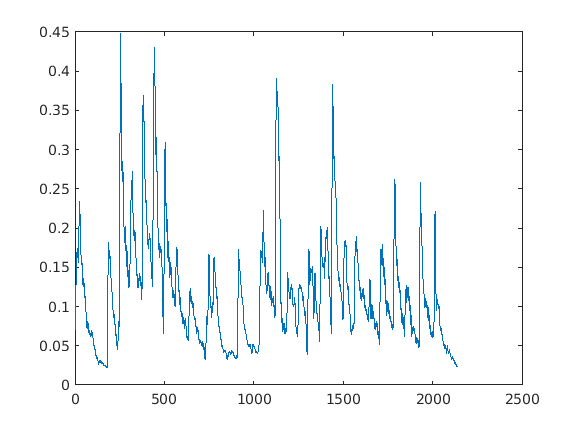

[pks, locs] = findpeaks(abs(y), ...
    'MinPeakDistance', 40, ...
    'MinPeakHeight', 0.02, ...
    'MinPeakProminence', 0.02);
% envelope = smooth(interp1(locs, pks, index, 'pchip'), 800);
envelope = smooth(pks, 7);
plot(envelope);

峰值定位

[pks2, locs2] = findpeaks(envelope, ...
    'MinPeakDistance', 25, ...
    'MinPeakHeight', 0.1, ...
    'MinPeakProminence', 0.03);
loc_seg = locs(locs2);

作图

plot(len/fs, y, 'c');
% hold on
% plot(loc_seg / fs, pks2, 'bo', 'MarkerFaceColor', 'b', 'markersize', 4);
% ylabel('Amplitude');
% xlim([0, max(len) / fs]); ylim([-0.6, 0.6]);
% title('Note Detecting');

## 2. 节拍计算

### 主要思想

- 根据分割的信息对音符进行分离，计算音符时长。

- 从中选取最小的音符间隔，做近似得到最小八分之一拍长。